sizeP = 5;
minI = 1200;
maxI = inf;
ecc = 0;
minLikelihood = 52;

J = imgaussfilt(I, sizeP/5);

tic;
particles = MLDetector(I,minI,maxI,ecc,sizeP);
toc

Elapsed time is 12.931753 seconds.


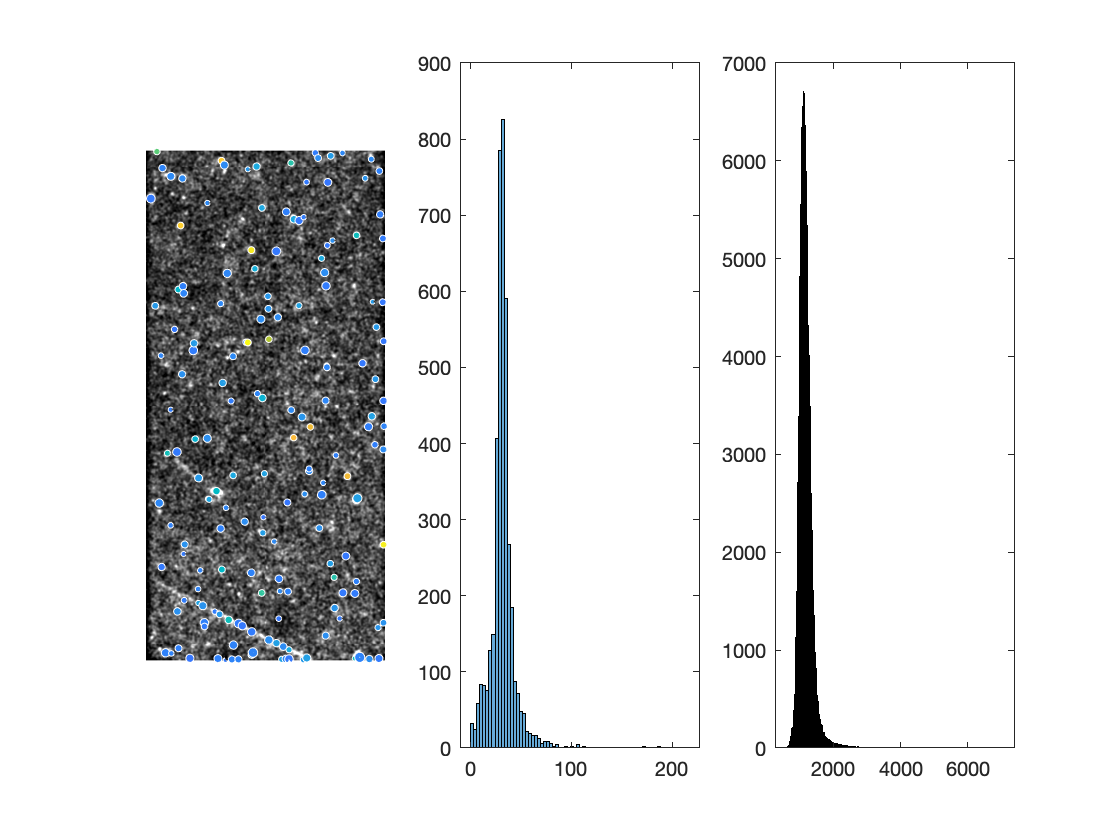


rgb = [particles.L]';
rgb = rgb - min(rgb);
rgb = rgb / max(rgb);
rgb = ind2rgb(uint8(round(rgb*256)),parula(256));
rgb = permute(double(rgb),[1 3 2]);

f = figure(1);
subplot(1,3,1);
imshow(imadjust(J));

hold on;
if ~isempty(particles)
    for i = 1:size(particles,2)
        if particles(i).L > minLikelihood
            viscircles([particles(i).ux particles(i).uy], particles(i).s,'Color',rgb(i,:));
        end
    end
end

hold off;


subplot(1,3,2);
histogram([particles.L]');

subplot(1,3,3);
histogram(J(:));